clear
% #1601
syms x;
y1=0.25*x^2

$$y1 = \frac{x^{2}}{4}$$

y2=3*x-0.5*x^2

$$y2 = 3\,x-\frac{x^{2}}{2}$$

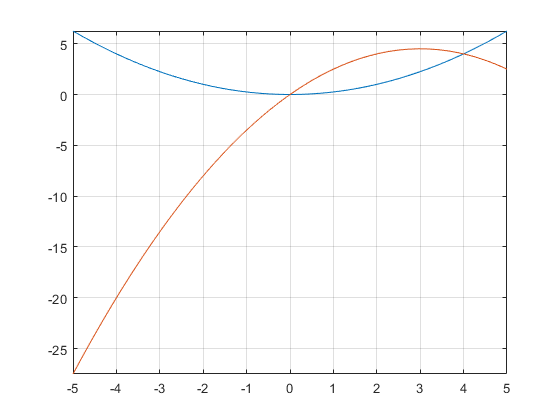


fplot(y1)
hold on
fplot(y2)
hold off
grid


syms x y;
slv1=solve(y==0.25*x^2,y==3*x-0.5*x^2)

slv1 = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


slv1.x

$$ans = \left(\begin{array}{c} 0\\ 4 \end{array}\right)$$


S=int(y2-y1,x,0,4)

$$S = 8$$

% 8

% #1602
syms x y;
f1=x*y-4*sqrt(2)

$$f1 = x\,y-4\,\sqrt{2}$$

f2=x^2-6*x+y^2

$$f2 = x^{2}-6\,x+y^{2}$$

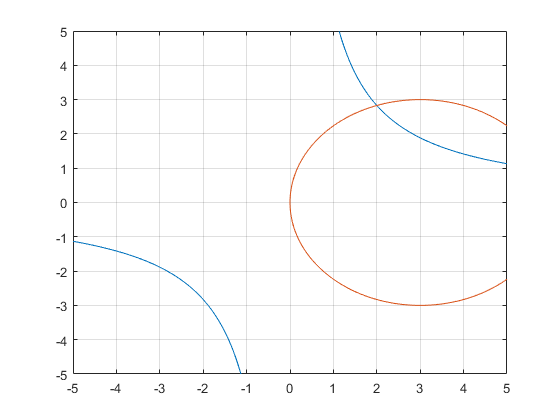

% y=0,x=4

fimplicit(f1)
hold on
fimplicit(f2)
grid on
hold off


slv=solve(f1,f2)

slv = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


slv.x

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{{\sigma_{1}}^{2}}{2}-\sqrt{2}\,\sigma_{1}+4\\ 2 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\sqrt{2}}{3}+\frac{16}{9\,{\left(\frac{\sqrt{27}\,\sqrt{2144}}{27}+\frac{164\,\sqrt{2}}{27}\right)}^{1/3}}-{\left(\frac{\sqrt{27}\,\sqrt{2144}}{27}+\frac{164\,\sqrt{2}}{27}\right)}^{1/3} \end{array}$$


y1=4*sqrt(2)/x

$$y1 = \frac{4\,\sqrt{2}}{x}$$

y2=sqrt(6*x-x^2)

$$y2 = \sqrt{6\,x-x^{2}}$$

S=int(y2-y1,x,2,4)

$$S = 9\,\mathrm{asin}\left(\frac{1}{3}\right)-4\,\sqrt{2}\,\log\left(2\right)+\sqrt{8}$$

% #1603
syms t;
x=12*cos(t)+5*sin(t)

$$x = 12\,\cos\left(t\right)+5\,\sin\left(t\right)$$

y=5*cos(t)-12*sin(t)

$$y = 5\,\cos\left(t\right)-12\,\sin\left(t\right)$$

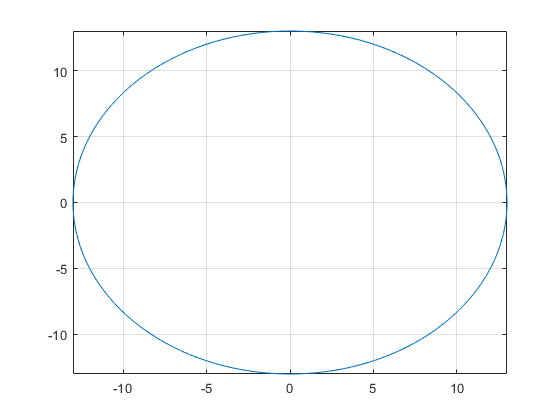


fplot(x,y)
grid


% S= int (t1-t2) y(t)*diff(x) dt
S=int(y*diff(x),t,0,2*pi)

$$S = 169\,\pi$$

% 169*pi

% #1604
syms t a;
x=a*cos(t)^3

$$x = a\,{\cos\left(t\right)}^{3}$$

y=a*sin(t)^3

$$y = a\,{\sin\left(t\right)}^{3}$$


% ezplot(x/a,y/a)

% dx=diff(x)
f=y*diff(x)

$$f = -3\,a^{2}\,{\cos\left(t\right)}^{2}\,{\sin\left(t\right)}^{4}$$

% -3*a^2*cos(t)^2*sin(t)^4

S=int(y*diff(x),t,0,-2*pi)

$$S = \frac{3\,\pi \,a^{2}}{8}$$

% (3*pi*a^2)/8

% #1605
syms theta;
rho=4/cos(theta-pi/6)

$$rho = \frac{4}{\cos\left(\theta -\frac{\pi }{6}\right)}$$

% pi/6<=theta<=pi/3

% S = 1/2 int (alpha-beta)  rho^2 d_theta
S=1/2*int(rho^2,theta,pi/6,pi/3)

$$S = \frac{8\,\sqrt{3}}{3}$$

% (8*3^(1/2))/3

% #1606
syms a theta;
rho1=a*cos(theta)

$$rho1 = a\,\cos\left(\theta \right)$$

rho2=2*a*cos(theta)

$$rho2 = 2\,a\,\cos\left(\theta \right)$$

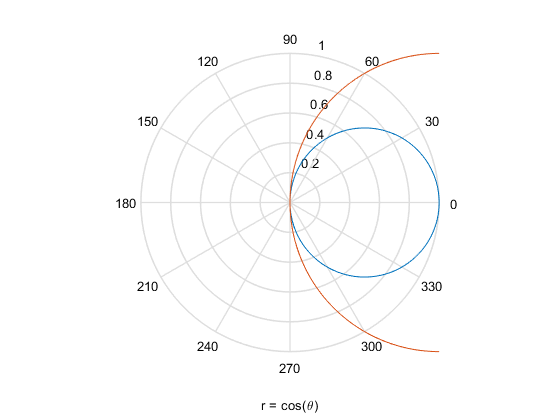


ezpolar(rho1/a)
hold on
ezpolar(rho2/a)
grid on
hold off


S1=1/2*int(rho1^2,0,2*pi)

$$S1 = \frac{\pi \,a^{2}}{2}$$

S2=1/2*int(rho2^2,0,2*pi)

$$S2 = 2\,\pi \,a^{2}$$

S=S2-S1

$$S = \frac{3\,\pi \,a^{2}}{2}$$

% (3*pi*a^2)/2

% #1607
syms theta a;
rho=sin(theta/2)^2

$$rho = {\sin\left(\frac{\theta }{2}\right)}^{2}$$

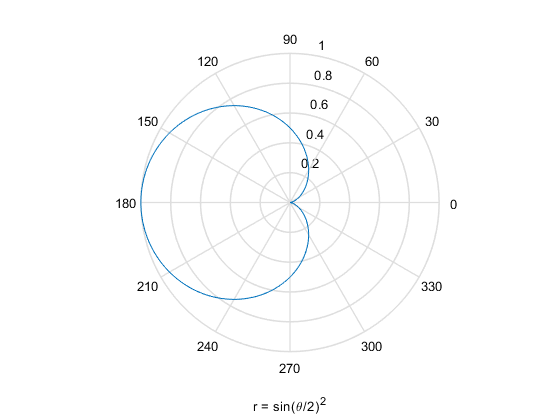


ezpolar(rho)


% S = int (alfa-beta) rho^2 d_theta
S=1/2*int(rho^2,0,pi/2)

$$S = \frac{3\,\pi }{32}-\frac{1}{4}$$

% (3*pi)/32 - 1/4

% #1608
syms a theta;
rho=a*sin(3*theta)

$$rho = a\,\sin\left(3\,\theta \right)$$

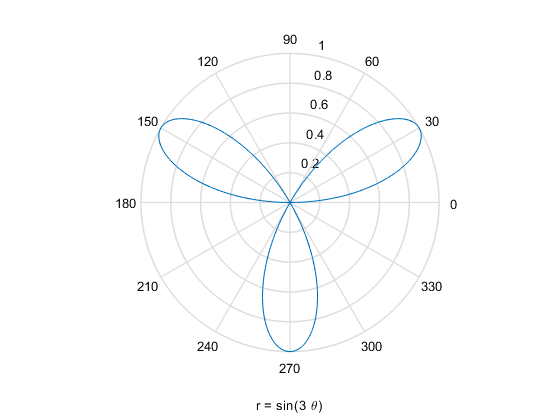


ezpolar(rho/a)


% S = int (alfa-beta) rho^2 d_theta
S=1/2*int(rho^2,theta,0,pi/3)

$$S = \frac{\pi \,a^{2}}{12}$$

% (pi*a^2)/12

% #1609
syms theta;
rho1=2*cos(theta)

$$rho1 = 2\,\cos\left(\theta \right)$$

rho2=1

rho2 =      1


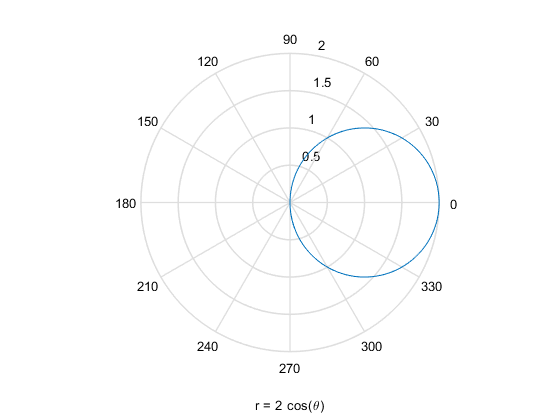


ezpolar(rho1)


S2=1/2*int(rho1^2-1,-pi/3,pi/3)

$$S2 = \frac{\pi }{3}+\frac{\sqrt{3}}{2}$$

% pi/3 + 3^(1/2)/2
